**Simple simulation of the chemostat**

strategy = 1×10 cell array
    {'Mixotroph'}    {'Osmoheterotroph'}    {'Osmoheterotroph'}    {'Osmoheterotroph'}    {'Light limited'}    {'Light limited'}    {'Nutrient limited'}    {'Mixotroph'}    {'Mixotroph'}    {'Mixotroph'}


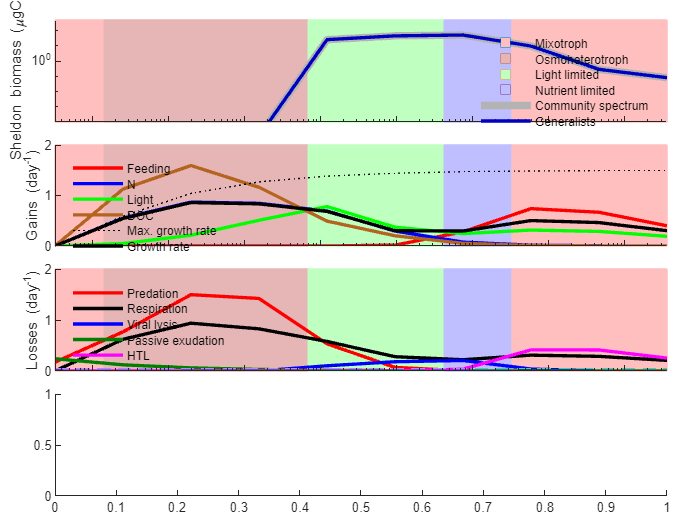

Error using calllib
Method was not found.

Error in getTheta (line 14)
theta = calllib(loadNUMmodelLibrary, 'f_gettheta', theta);

Error in calcTrophicLevel (line 21)
theta = getTheta(p);

Error in 

%
% Choose a setup:
%
sSetup = "GeneralistsOnly";
%
% Chemostat parameters:
%
Light = 60;
Mixing = -1.3;
mortHTL = 0.5;
%
% Run simulation:
%
p = parametersChemostat( eval( strcat('setup',sSetup) ) );
p.tEnd = 1000;

p.d = 10^Mixing;
setHTL(10^mortHTL, 0.05, true, false);

sim = simulateChemostat(p, Light, 10);
%
% Output:
%
plotSizespectrum(sim);

sim = calcFunctions(sim, bPrintSummary=true);
tiledlayout(2,1)
nexttile
panelRespiration(p, sim.rates,1)
nexttile
panelRespiration(p, sim.rates,2)